# Voltage Sensitive Dye Imaging Pipeline

clc; clear; close all;

Dataset: image_stack [540x240x1500]
Interleave contrast A/B: 62.102 / 17.112 (ratio 3.63). Higher=A
Reference (interleave space): 75-824, alpha=1.00, sigma=[1.0 1.0 0.1]


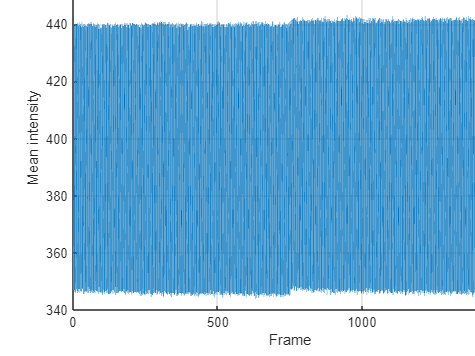

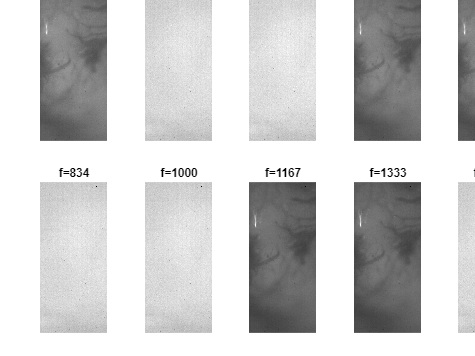

config = hdf5_parser('converted__1000/led_E1B1.h5','image_stack', ...
        'frame_rate',1001.34,'memory_gb',8,'output_folder','data/parsed_1000', ...
        'num_preview_frames',10,'make_plots',true); %to visualize dataset metrics

%dataset 500hz = 500.67 fps
%dataset 100hz = 1001.34 fps

visualize_raw_avi('converted__1000/led_E1B1.h5', 'image_stack', ...
        'channel', 'high_contrast', ... %original, low_contrast, high_contrast
        'clip_percentiles', [0 100], ... %contrast clipping, using full range
        'frame_rate', 1001.34, ...
        'output_filename', 'data/parsed_1000/led_E1B1_structural.avi', ...
        'quality', 95, ...
        'max_frames', inf, ...
        'downsample_factor', 1, ...
        'colormap_name', 'gray'); %produces video from raw dataset

Analyzing interleave pattern...
Channel A has higher contrast (62.10 vs 17.11)
Channel: high_contrast (use_interleave: A), Effective FPS: 500.67
Processing range: frames 1 to 1500 (1500 raw frames)
Expected output frames: 750 (after channel selection and downsampling)
Calculating intensity range for clipping...
Clipping range: [0.0, 1197.0] (percentiles: [0.0, 100.0])
Writing video to: data/parsed_1000/led_E1B1_structural.avi
Processing frames...
Video saved: data/parsed_1000/led_E1B1_structural.avi
Total frames written: 750 (expected: 750)
Duration: 1.498 seconds at 500.670 fps

=== Summary ===
Input: converted__1000/led_E1B1.h5
Dataset: image_stack [540x240x1500]
Channel: high_contrast
Clipping percentiles: [0.0, 100.0]
Effective frame rate: 500.67 fps
Output: data/parsed_1000/led_E1B1_structural.avi
File size: 20.52 MB


vsd_motion_correct('converted__1000/led_E1B1.h5', ...
      'DatasetName','image_stack', ...
      'OutputFolder','data/motion_compensated_1000', ...
      'ReferenceFrames',70:200, ...        %interleaved indexing, but takes only structural frames
      'OF', struct('alpha',1.0,'sigma',[2.0,2.0,0.2;1.0,1.0,0.1], ... %[X,Y,T(sturct);X,Y,T(func)]
                   'weight',[0.8,0.2],'quality_setting','quality', ...
                   'bin_size',1,'buffer_size',100, ...
                   'save_w',true,'save_meta_info',true,'verbose',true));

Loading HDF5 dataset "/image_stack" from converted__1000/led_E1B1.h5 ...
Data: 540x240x1500 (H x W x T)
Assigning structural/functional frames based on pair-wise contrast...
Assigned 750 structural and 750 functional frames.
Using 65 mapped reference frames in structural indexing.
Creating Flow-Registration input: data\motion_compensated_1000\temp_multichannel.h5
Flow-Registration options configured.
Reader OK — Channels: 2 | Frames: 750 | Size: 240x540 | Type: uint16
Running compensate_recording (full pipeline)...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.
Motion correction finished.
Consolidated output saved to: data\motion_compensated_1000\led_E1B1_vsd_corrected.h5

Motion statistics:
  Mean displacement: 0.46 ± 0.05 px
  Max displacement: 5.73 px
  Mean divergence: -0.0162 ± 0.0058
  Mean translation: 0.12 ± 0.07 px
Temporary Flow-Registration input removed.
Done.


%**SUPER IMPORTANT**= make sure the flow_registration toolbox is configured
%note =displacement_fields output file (w.h5) are overwritten (change file name to preserve)

% after motion compensation is finished
delete(gcp('nocreate')); %close parallel poool processing

% produce output files to video
vsd_h5_to_videos('data/motion_compensated_1000/led_E1B1_vsd_corrected.h5', ...
      'OutputFolder','data/motion_compensated_1000/', ...
      'FPS',500.67, ...
      'ClipPercentiles',[0 100], ...
      'Codec','Motion JPEG AVI'); %produces video from motion compensated dataset

Loading HDF5 file: data/motion_compensated_1000/led_E1B1_vsd_corrected.h5
Found required datasets: structural, functional
Dataset "/structural": 540x240x750 (H x W x T)
Dataset "/functional": 540x240x750 (H x W x T)
Starting video generation with FPS=500.670, Codec=Motion JPEG AVI

Processing "structural" dataset (540x240x750)...
Computing intensity percentiles for scaling...
  Sampling frames and pixels for percentile calculation...
  Using stratified sample of 200/750 frames
  Sampling 12960/129600 pixels per frame (10.0%)
  Sampling progress: 20/200 frames (10.0%)
  Sampling progress: 40/200 frames (20.0%)
  Sampling progress: 60/200 frames (30.0%)
  Sampling progress: 80/200 frames (40.0%)
  Sampling progress: 100/200 frames (50.0%)
  Sampling progress: 120/200 frames (60.0%)
  Sampling progress: 140/200 frames (70.0%)
  Sampling progress: 160/200 frames (80.0%)
  Sampling progress: 180/200 frames (90.0%)
  Sampling progress: 200/200 frames (100.0%)
  Percentile calculation complet

% diagnostic tool in case photobleaching was observed earlier
% bleaching_metrics = observe_bleaching('data/motion_compensated/led_E0B0_vsd_corrected.h5', ...
%                       'Dataset','functional', ...
%                       'FrameRate',250.335, ...       
%                       'SmoothWin',11, ...
%                       'FitDouble',false, ...
%                       'SavePrefix','data/photobleach/trial');

% sanity check for fluorescence
% global_fluorecence_check = vsd_sanity_check('data/motion_compensated/led_E0B0_vsd_corrected.h5', 'Dataset','functional');

% run on motion compensated data
run run_trial_averaging.m


% vsd_fluorescence('data/motion_compensated/led_E1B1_vsd_corrected.h5', ...
%     'Dataset', 'functional', ...
%     'Mode', 'F', ...                 % 'F' (Fluorescence), 'dff' (deltaF/F), or 'both'
%     'BaselineIdx', 1:375, ...
%     'Bin', 2, ...                    % temporal binning: improves SNR ~ sqrt(bin)
%     'DisplayFPS', 125, ...          % 250.335/bin or 500.67/bin = DisplayFPS
%     'Sigma', 1.5, ...                 % Gaussian smoothing (pixels)
%     'MedianWin', 0, ...               % median filter window (0=off, else odd int >3)
%     'ClipLowPct', 1, ...               % clip bottom X% of F0 to avoid division noise
%     'ClipHighPct', 99, ...             % clip top Y% for contrast when viewing F
%     'Mask', [], ...                    % logical HxW
%     'Out', 'data/led_E1B1_125fps_unclipped.avi', ...  % empty=don’t save
%     'ShowColorbar', true, ...
%     'ColormapF', 'none', ...              
%     'ColormapDFF', 'none', ...          
%     'IntensityLimitsF', [], ...   % intensity limits
%     'IntensityLimitsDFF', [], ...
%     'UseSymmetricDFF', true);

Reading data/motion_compensated/led_E1B1_vsd_corrected.h5 /functional ...
Loaded data: 540x516x750 (H x W x T)
Binned from 750 to 375 frames (bin=2)
Applying Gaussian filter (sigma=1.5)...
Setting up video writer for data/led_E1B1_125fps_unclipped.avi (FPS=125)...
Displaying movie (mode=f)...
Saved movie to data/led_E1B1_125fps_unclipped.avi (FPS=125, bin=2)
Function completed successfully.


% vsd_overlay('data/motion_compensated/led_E0B3_vsd_corrected.h5', ...
%     'Dataset', 'functional', ...
%     'Mode', 'dff', ...
%     'BaselineIdx', 1:100, ...
%     'Bin', 5, ...
%     'DisplayFPS', 125, ...
%     'Sigma', 1, ...
%     'MedianWin', 3, ...               % median filter window (0=off, else odd int >3)
%     'IntensityLimitsF', [ ], ...  % use approx [365, 370] for 1000fps; [395, 400] for 500fps
%     'Out', 'data/led_E0B3_100-5-1-3.avi', ...
%     'ShowColorbar', true, ...
%     'ColormapF', 'winter', ...  % use spring, winter, summer for best results
%     'StructuralDataset', 'structural', ...
%     'StructuralAlpha', 0.3, ...
%     'ShowDisplay', false, ...
%     'TrimEnd', 0, ...              % Remove last N frames (possible stray light)
%     'SmoothDisplay', 'none', ... % 'none' or 'nearest'(less pixelated) or 'bilinear'(anti-aliasing)
%     'ColormapAlpha', 0.28);          % 0.5 means 50% colormap opacity

Reading data/motion_compensated/led_E0B3_vsd_corrected.h5 /functional ...
Loaded functional data: 540x516x750 (H x W x T)
Loaded structural data: 540x516x750
Binned from 750 to 150 frames (bin=5)
Applying median filter (window=3)...
Applying Gaussian filter (sigma=1)...
Computing dF/F...
Setting up video writer for data/led_E0B3_100-5-1-3.avi (FPS=125)...
Displaying movie (mode=dff)...
Saved movie to data/led_E0B3_100-5-1-3.avi (FPS=125, bin=5)
Function completed successfully.


vsd_overlay('data/averaged_movie_E0B0-B3_unbinned.h5', ...
    'Dataset', 'functional_dff', ...
    'Mode', 'F', ...
    'BaselineIdx', 1:2, ...
    'IntensityLimitsF', [-0.01, 0.03], ...
    'Out', 'data/averaged_movie_E0B0-B3_unbinned.avi', ...
    'ShowColorbar', true, ...
    'ColormapF', 'winter', ...  % use spring, winter, summer for best results
    'StructuralDataset', 'structural', ...
    'StructuralAlpha', 0.3, ...
    'ShowDisplay', false, ...
    'SmoothDisplay', 'none', ... % 'none' or 'nearest'(less pixelated) or 'bilinear'(anti-aliasing)
    'ColormapAlpha', 0.38);       

Reading data/averaged_movie_E0B0-B3_unbinned.h5 /functional_dff ...
Loaded functional data: 540x516x750 (H x W x T)
Loaded structural data: 540x516x750
Setting transparency threshold to lower intensity limit: -0.01
Setting up video writer for data/averaged_movie_E0B0-B3_unbinned.avi (FPS=50)...
Displaying movie (mode=f)...


Saved movie to data/averaged_movie_E0B0-B3_unbinned.avi (FPS=50, bin=1)
Function completed successfully.


% diagnostic tool
single_frame_grabber('data/averaged_movie_E0B0-B3_unbinned.h5', 7);

Choose an action:
1: Save this frame
2: Next frame
3: Previous frame
4: Exit
5: Jump to specific frame
Choose an action:
1: Save this frame
2: Next frame
3: Previous frame
4: Exit
5: Jump to specific frame
Exiting frame viewer.


Parallel pool using the 'Processes' profile is shutting down.


% run on unbinned run_trial_averaged.m output file
run PCA_ICA_decomp.m
run reconstruct.m
run post_reconstruction.m